## find IRF height from each trial 

Convolution in signal generation and in fMRI research. 

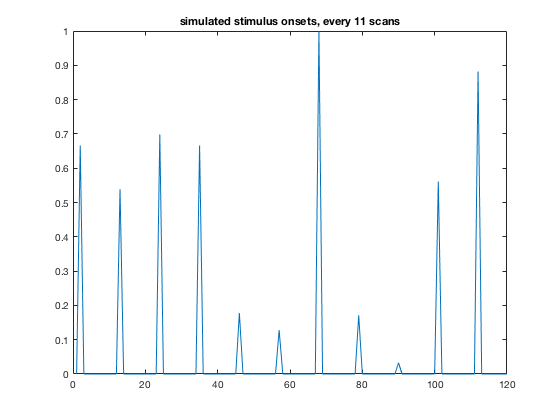

%First, make onsets for 120 MR images, with IRF varying in height
clear all
heights = rand(1,11); % 11 events
onsets = zeros(1, 120); 
onsets(2:11:end) = heights; %simple case where a stimulus is on every 11 scans
plot(onsets), title ('simulated stimulus onsets, every 11 scans')

% now we make a kernel
% the inverted gamma function is nice because it looks like fMRI in V1
% let's make one that is 10 scans long
kernel = (1./gamma(0.1:0.5:5))

kernel =     0.1051    0.6715    1.0511    1.1192    0.9556    0.6995    0.4550    0.2690    0.1468    0.0747


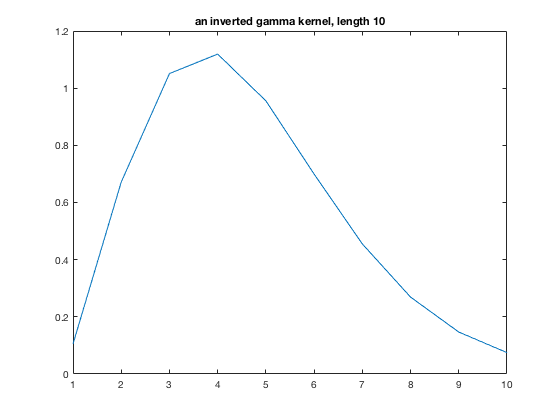

figure
plot(1./gamma(0.1:0.5:5)), title('an inverted gamma kernel, length 10')

Now we just convolve the onsets with the kernel and plot the result

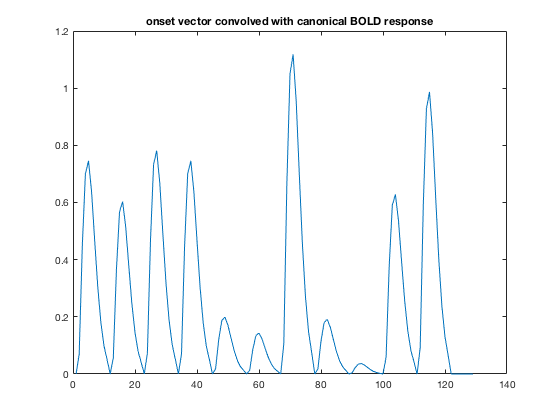

convolution  = conv(onsets, kernel, 'full'); 
figure
plot(convolution), title('onset vector convolved with canonical BOLD response')

So this basically puts each 10 second kernel at the location where the onset is. There were 1 seconds between onsets, so this is like copy paste, but how about when the kernel is longer than the interval between onsets? 

kernel = (1./gamma(0.1:0.25:5)) % this Kernel is twice as long

kernel =     0.1051    0.3928    0.6715    0.8989    1.0511    1.1221    1.1192    1.0575    0.9556    0.8312    0.6995    0.5716    0.4550    0.3537    0.2690    0.2006    0.1468    0.1056    0.0747    0.0521


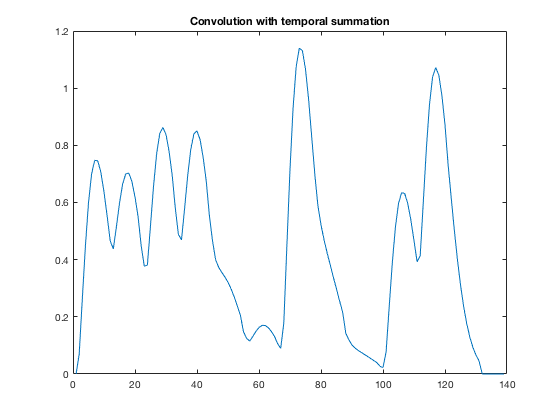

convolution  = conv(onsets, kernel, 'full'); 
figure
plot(convolution), title('Convolution with temporal summation')

When the convolution encounters overlap, then temporal summation results, because convolution is a process of shifting the kernel, multiplying element-wise, and summation to one new value, rinse and repeat. Because of the shifting and summing up portion of the algorithm, if the Kernel spans multiple, similar events, it will show temporal summation. 

 This is more interesting with variable inter-onset times. 

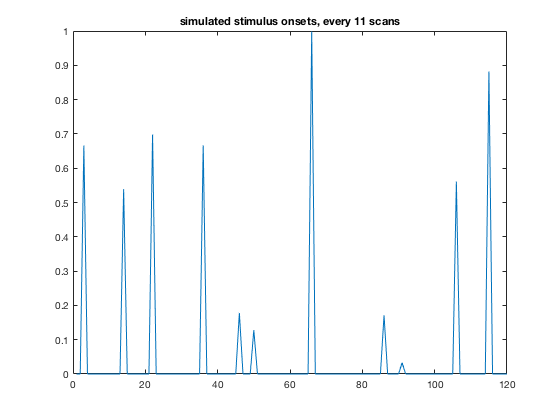

onsets = zeros(1, 120);
onsets([3 14 22 36 46 50 66 86 91 106 115]) = heights; %simple case where a stimulus is on every 11 scans
plot(onsets), title ('simulated stimulus onsets, every 11 scans')

Now we convolve these onset times with the same kernel

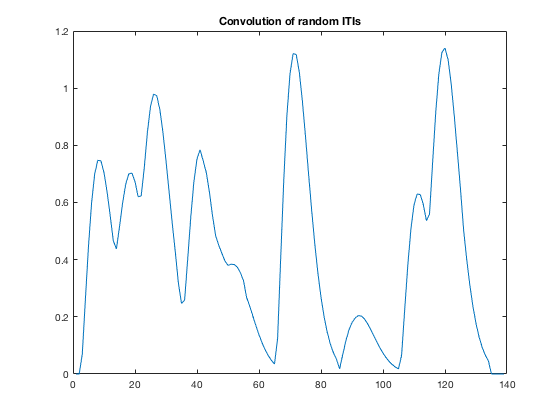

convolution  = conv(onsets, kernel, 'full'); 
figure
plot(convolution), title('Convolution of random ITIs')

Longer intervals between onsets prompt complete reduction to baseline, temporal proximity prompts smeared, overlapping events. How about gamma-shaped responses to stimuli that are longer than one image? 

## Deconvolution and amplitude estimation for each trial

deconvolution is the process where we wish to estimate the Kernel from known data and known event-times. This is a version of the so-called inverse problem, and we solve it with a regression. Let's start with the simulated we we have: 

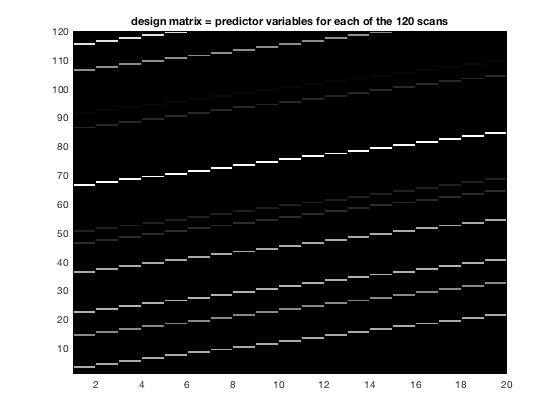

% for a regression, we need a "design matrix" X
X = zeros(length(convolution(1:120)), 20); % we know the convolution and the kernel we used had 20 values
temp = onsets';  % IMPORTANT: These onsets have the actual heights used in the forward computation
for i=1:20
X(:,i) = temp; % note the gray scale difference sin the design matrix, reflecting different heights
temp = [0;temp(1:end-1)];
end
pcolor(X), colormap('gray'), title('design matrix = predictor variables for each of the 120 scans')

ans =     20   120


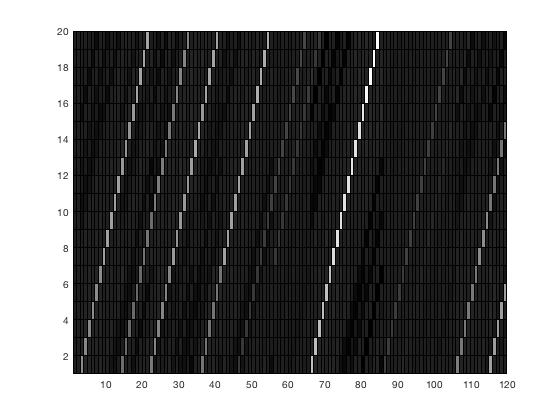

% now invert design matrix X
PX = pinv(X); size(PX), figure, pcolor(PX), colormap('gray')


% estimate kernel, h
h = PX* convolution(1:120)';

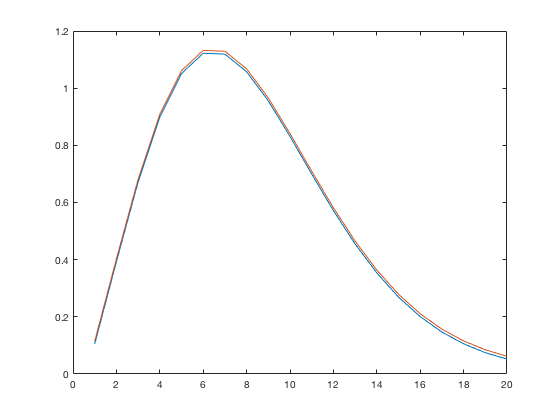

% and now.... drum roll
figure, plot(h), hold on, plot(kernel+0.01)

But normally we do not know the height, in fact the amplitude of the siongle trial BOLD is often what we want in EEG-fMRI. So let's just get the shape of the IRF, assuming the height is always one (1) ...

% assuming that each event = 1 instead of different amplitude/height for
% each trial
[h] = hrf_est(convolution(1:120)',[3 14 22 36 46 50 66 86 91 106 115], 20); 

ans =     20   120


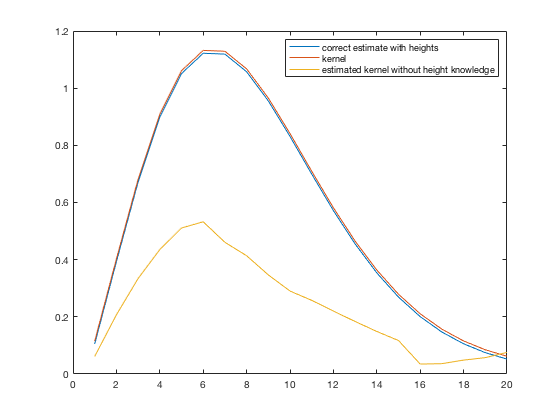

plot(h)
legend('correct estimate with heights', 'kernel', 'estimated kernel without height knowledge')

This gives us an estimate of the Kernel, which looks faitly good with only 11 trials, despite not knowing the magnitude. Now we need asecon regression that uses the knowledge of the (1) empirical data, (2) onset times, (3) shape of the IRF, to estimate the height of the IRF in each trial. To this, we make a function that doe sthe forward solution of this regression, and then invert it, estimating the regression coefficients, just like above in convolution. This time, the betas are the magnitudes if the estimated BOLD in each trial though. 

The function will look like this: 

[outvec] = irf_convolve(heightvec, inputs)

inputs.kernel is a vector (often around 5-20 elements long) of the expected IRF shape

inputs.onsetvec is a vector with zeros for each TR in the BOLD time series, and the number 1 at those TRs where there is a stimulus onset

heightvec is a vector, corresponding to magnitudes of each IRF, for each event. Must have the same length as onsets i.e., length(onsetvec(onsetvec ==1))

%let's run it! 
onsets(onsets>0) = 1; 
inputs.onsetvec = onsets; 
inputs.kernel = h; 
heightvec = heights; 
[outvec] = irf_convolve(heightvec, inputs)

outvec =          0         0    0.0410    0.1380    0.2227    0.2900    0.3403    0.3548    0.3070    0.2758    0.2311    0.1933    0.1717    0.1798    0.2341    0.2793    0.3126    0.2985    0.3112    0.2808    0.2612    0.2803    0.3009    0.3722    0.4224    0.4556    0.4520    0.3847    0.3076    0.2616    0.2287    0.2108    0.1944    0.1283    0.1039    0.1228    0.1623    0.2480    0.3240    0.3804    0.4078    0.3071    0.2758    0.2311    0.1933    0.1827    0.1836    0.1820    0.1767    0.1769


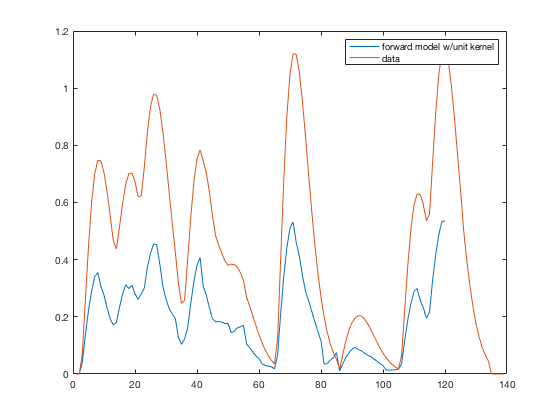

figure, plot(outvec), hold on, plot(convolution)
legend('forward model w/unit kernel', 'data')

The blue line (forward model) is smaller, because the IRF underestimated the data (figure above). that's actually good. 

% now let's invert this function and get those single trial magnitudes. We use nonlinear regression and iterative parameter estimation this time, because that model is harder to invert as a deign matrix inversion, at least I could not do it.  So again, we find the height parameters through iteration, i.e. going through parameter space until matlab finds the best fit. The function we use to do this is called nlinfit. 

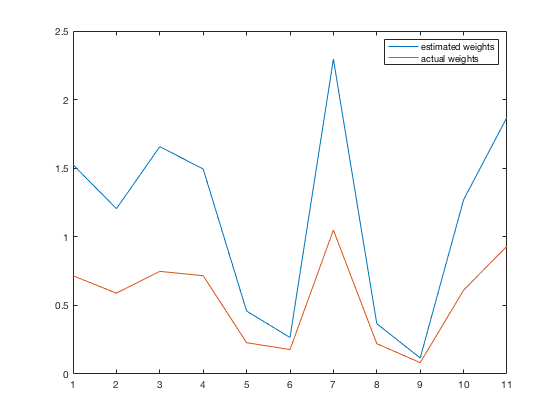

[BETA,R,J,COVB,MSE] = nlinfit(inputs, convolution(1:120), @irf_convolve, ones(1,11));
figure, plot(BETA), hold on, plot(heightvec+0.05), legend('estimated weights', 'actual weights')

nlinfit wants 

1) the inputs (the design variables, or what we know) 

2) the data to fit

3) the function with an @ i.e. @irf_convolve

4) starting values for the betas (here for the 11 onsets), we can use 1 here uniformly (ones(1,11)). 